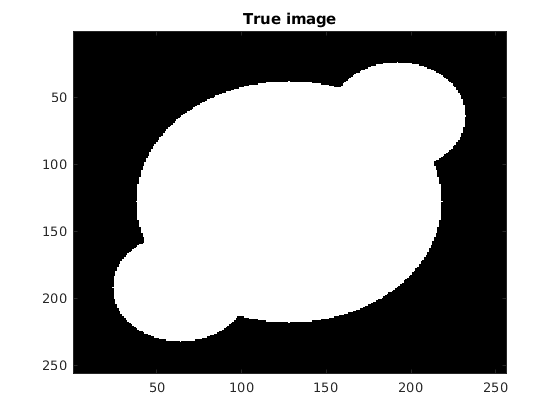

clc;
clear;
close all;

% set rng seed
rng(1000);

% Import image
I = imread('circle.png');
m_true = 146*double(I);

% Get the number of pixels in the vertical and horizontal direction (N1, and N2)
[N1, N2] = size(m_true);
N = N1 * N2;

% Generate x and y axis
x=linspace(0,N2,N2);
y=linspace(0,N1,N1);
[xx,yy] = meshgrid(x,y);

% draw the imported image
figure;
colormap gray;
imagesc(m_true);
title('True image');

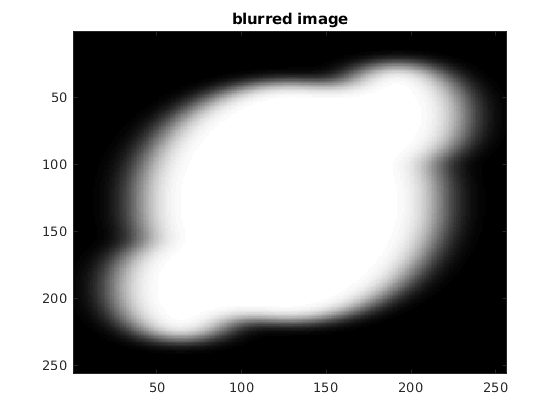

% Use different Gaussian blurring in x and y-direction
gamma1 = 5;
C1 = 1 / (sqrt(2*pi)*gamma1);
gamma2 = 12;
C2 = 1 / (sqrt(2*pi)*gamma2);

% blurring operators for x and y directions
K1 = zeros(N1,N1);
K2 = zeros(N2,N2);
for l = 1:N1
    for k = 1:N1
    	K1(l,k) = C1 * exp(-(l-k)^2 / (2 * gamma1^2));
    end
end
for l = 1:N2
    for k = 1:N2
    	K2(l,k) = C2 * exp(-(l-k)^2 / (2 * gamma2^2));
    end
end

% blur the image: first, K2 is applied to each column of I,
% then K1 is applied to each row of the resulting image
Ib = (K2 * (K1 * m_true)')';

% plot blurred image
figure;
colormap gray;
imagesc(Ib);
title('blurred image');

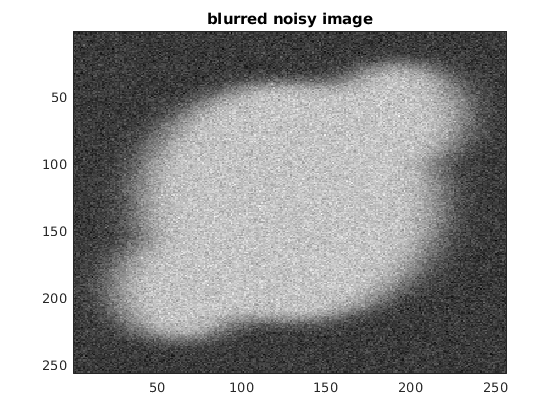

% add noise and plot noisy blurred image
Ibn = Ib + 16 * randn(N1,N2);
figure;
colormap gray;
imagesc(Ibn);
title('blurred noisy image');

%% Find optimal Tikhinov regularizer through L-curve criterion

% first construct the right hand side K'*d
K_Ibn = (K2 * (K1 * Ibn)')';

% calculate misfit and regularization values
alpha_list = logspace(-5,-2,50);
m_alpha = zeros(N,numel(alpha_list));
misfit = zeros(numel(alpha_list),1);
reg = zeros(numel(alpha_list),1);
for i=1:numel(alpha_list)
    % calculate m_alpha
    m_alpha(:,i) = pcg(@(in)apply(in,K1,K2,N1,N2,alpha_list(i)),K_Ibn(:),1e-6,1500);
    
    % calculate misfit and regularization term for alpha
    misfit(i) = norm((K2 * (K1 * reshape(m_alpha(:,i),N1,N2))')' - Ibn);
    reg(i) = norm(m_alpha(:,i));
end

pcg converged at iteration 880 to a solution with relative residual 8.5e-07.
pcg converged at iteration 814 to a solution with relative residual 1e-06.
pcg converged at iteration 786 to a solution with relative residual 8.7e-07.
pcg converged at iteration 730 to a solution with relative residual 9.9e-07.
pcg converged at iteration 700 to a solution with relative residual 8.7e-07.
pcg converged at iteration 657 to a solution with relative residual 8.6e-07.
pcg converged at iteration 610 to a solution with relative residual 9.9e-07.
pcg converged at iteration 580 to a solution with relative residual 9.1e-07.
pcg converged at iteration 544 to a solution with relative residual 9.5e-07.
pcg converged at iteration 510 to a solution with relative residual 9.9e-07.
pcg converged at iteration 481 to a solution with relative residual 8.9e-07.
pcg converged at iteration 443 to a solution with relative residual 9.6e-07.
pcg converged at iteration 425 to a solution with relative residual 9.2e-07.
p

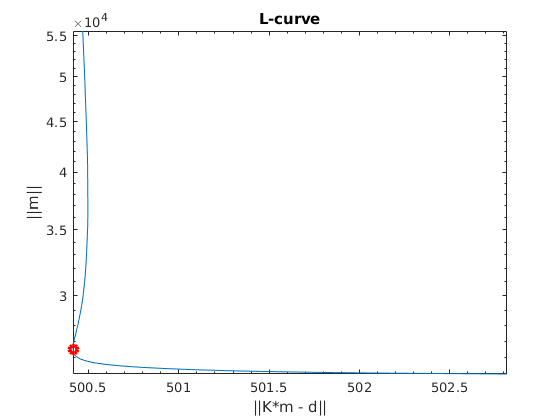

% plot L-curve
crit = 27; % set index of max curvature
figure; loglog(misfit, reg); hold on;
loglog(misfit(crit), reg(crit), 'ro', 'Linewidth', 3); % circle optimal value
xlabel('||K*m - d||'); ylabel('||m||'); title('L-curve');

%% Compute Tikhonov reconstruction with regularization parameter alpha
% i.e. compute m = (K'*K + alpha*I)\(K'*d)

% then set the regularization parameter 
alpha = alpha_list(crit);

% now solve the regularized inverse problem to reconstruct the 
% the image using preconditioned conjugate gradients (pcg) to solve the
% system in a matrix-free way using function "apply"
m_alpha = pcg(@(in)apply(in,K1,K2,N1,N2,alpha),K_Ibn(:),1e-6,1500);

pcg converged at iteration 40 to a solution with relative residual 7.4e-07.


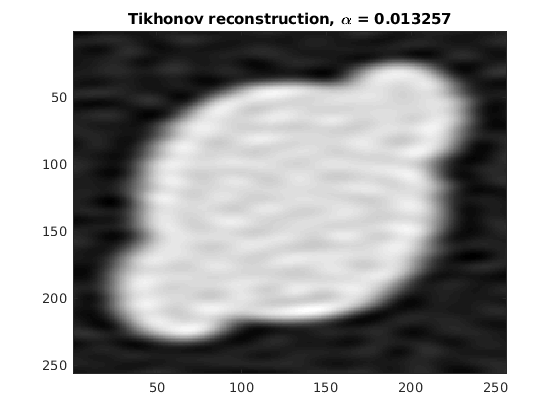

figure;
colormap gray;
imagesc(reshape(m_alpha,N1,N2));
title(['Tikhonov reconstruction, \alpha = ', num2str(alpha)]);

%% Find alpha that gives min norm between Tikhonov recon and real image

% calculate ||m_true - m_alpha|| for various alphas
alpha_list = logspace(-4,0,50);
m_alpha = zeros(N,numel(alpha_list));
L2 = zeros(numel(alpha_list),1);
for i=1:numel(alpha_list)
    m_alpha(:,i) = pcg(@(in)apply(in,K1,K2,N1,N2,alpha_list(i)),K_Ibn(:),1e-6,1500);
    L2(i) = norm(m_true(:) - m_alpha(:,i));
end

pcg converged at iteration 326 to a solution with relative residual 9.3e-07.
pcg converged at iteration 300 to a solution with relative residual 9.7e-07.
pcg converged at iteration 279 to a solution with relative residual 9.1e-07.
pcg converged at iteration 253 to a solution with relative residual 8.9e-07.
pcg converged at iteration 230 to a solution with relative residual 9.8e-07.
pcg converged at iteration 216 to a solution with relative residual 8.8e-07.
pcg converged at iteration 200 to a solution with relative residual 9.1e-07.
pcg converged at iteration 182 to a solution with relative residual 9.8e-07.
pcg converged at iteration 168 to a solution with relative residual 9.6e-07.
pcg converged at iteration 156 to a solution with relative residual 9e-07.
pcg converged at iteration 143 to a solution with relative residual 9.2e-07.
pcg converged at iteration 129 to a solution with relative residual 9.5e-07.
pcg converged at iteration 120 to a solution with relative residual 1e-06.
pcg

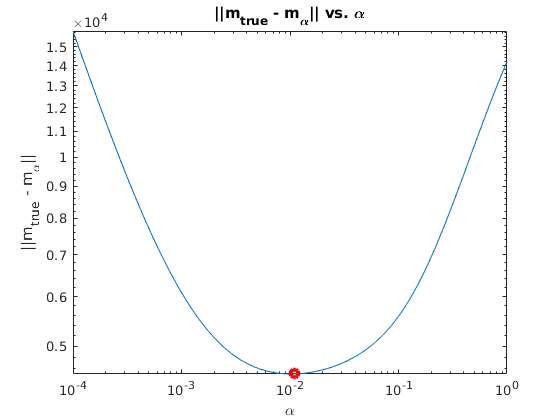

% get min alpha
[min_L2, idx] = min(L2);
min_alpha = alpha_list(idx);

% plot as the norms as a function of alpha
figure; loglog(alpha_list,L2); hold on; loglog(min_alpha, min_L2, 'ro', 'Linewidth', 3);
title('||m_{true} - m_{\alpha}|| vs. \alpha'); xlabel('\alpha'); ylabel('||m_{true} - m_{\alpha}||');